## Derivate function Model for Segway

Including equations and plotted results

### Equations:

For a full model including rolling resistance, damping 


$$ (m + m_w + \frac{I_w}{R^2}) \ddot{x}_C + m h \ddot{\gamma} \cos \gamma - m h \dot{\gamma}^2 \sin \gamma = \frac{(M - T_{damp} + \tau_{rolling})}{R}   \\
m h \ddot{x}_C \cos \gamma + m h^2 \ddot{\gamma} - m g h \sin \gamma = - (M - T_{damp}).
$$


where:

- Rolling resistance: $\tau_{rolling} = -\mu_{rolling} \cdot N \cdot R$

- Motor damping and friction =$T_{damp} = B \omega + B_0 sign(\omega) = B \left(\frac{\dot{x}_C}{R} -\dot{\gamma}\right) + B_0 sign\left(\frac{\dot{x}_C}{R} -\dot{\gamma}\right).$

-  $m$ is the mass of the pendulum, $m_w$ and $I_w$ are the mass and inertia of the wheel , $\gamma$ is the angle of the pendulum, $x_c =\varphi R$ is the displacement of the center of mass. Pendulum inertia is ignored here because it is far more smaller than ${\textrm{mR}}^2$ or $m_w R^2$

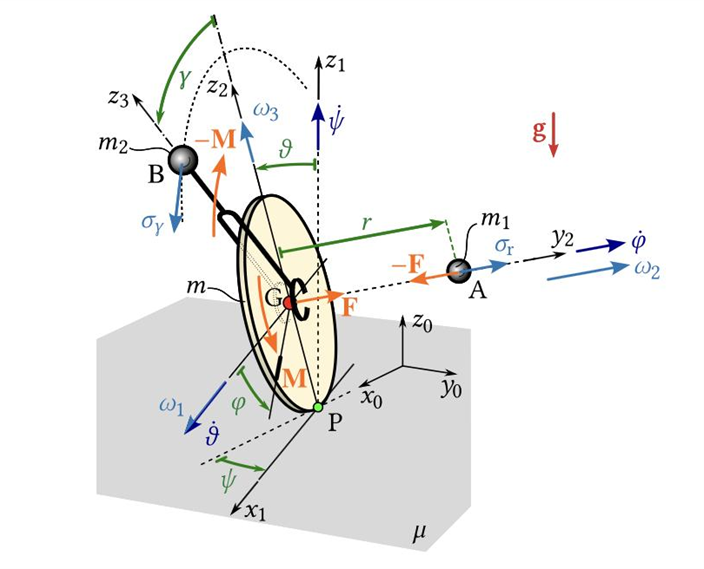

### Controller:

PD controller

- Balance mode: $M = K_{\gamma} (\gamma - \gamma_{\text{desired}}) + K_{\dot{\gamma}} \dot{\gamma} $

- Velocity mode: $M = K_\gamma (\gamma - \gamma_d) + K_{\dot{\gamma}} (\dot{\gamma} - \dot{\gamma}_d) + K_v (v - v_d) $

- Position mode: $M = K_\gamma (\gamma - \gamma_d) + K_{\dot{\gamma}} (\dot{\gamma} - \dot{\gamma}_d) + K_v (v - v_d) + K_s (x - x_d) $

### Parameters:

Measured constants:

Tuned controller params, friction terms and mass

Raw data sets are in "./Data/P1.0x3.csv", "./Data/P1.0x3(2).csv" for position mode with target position 1.0m for three trials each file, and "./Data/V0.5x3.csv", "./Data/V0.5x3(2).csv" for velocity mode for 0.5m/s for three trials each file. Some of the raw data for the velocity mode is faulty as discussed in the meeting, I removed them while tuning.

For the simulated data after tuned: They are compared with position mode and velocity mode real data, where both of them are filtered by "`UnivariateSpline" `from` "scipy``.``interpolate". `mThe simulated data and combined with real data after filtering are in "./Data/Position_tuning_results.csv" and "./Data/Velocity_tuning_results.csv".

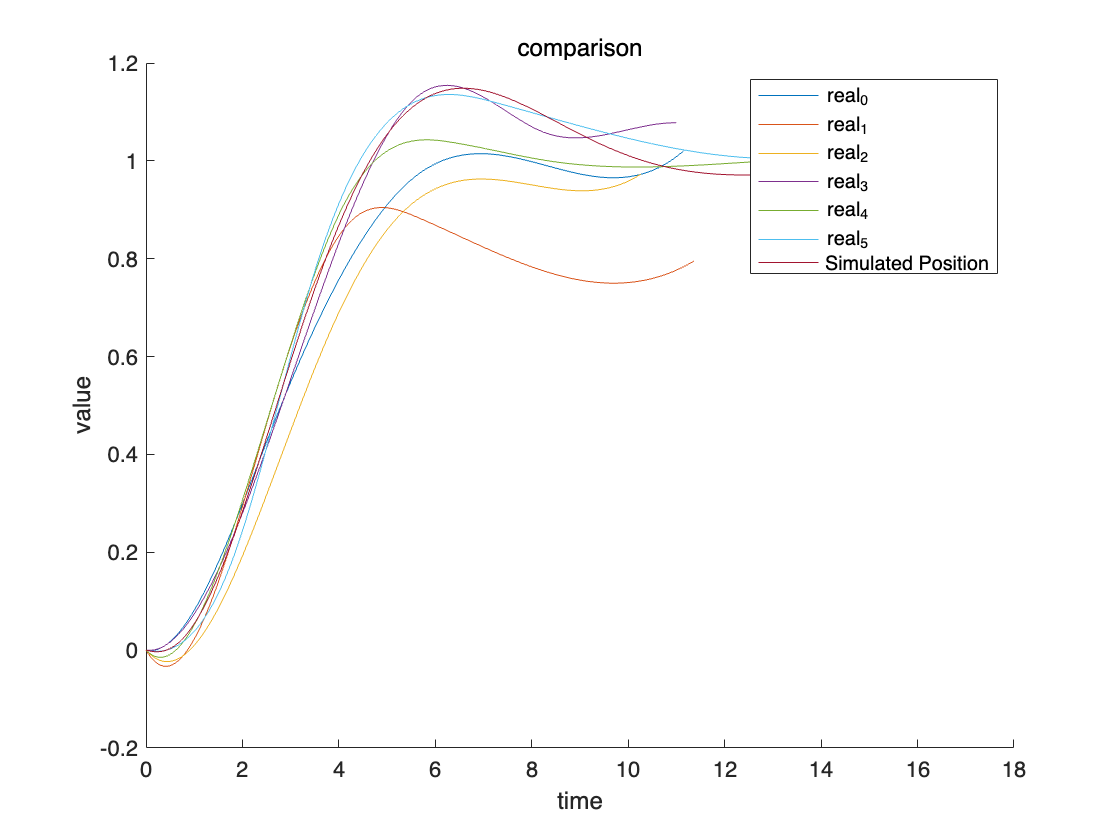

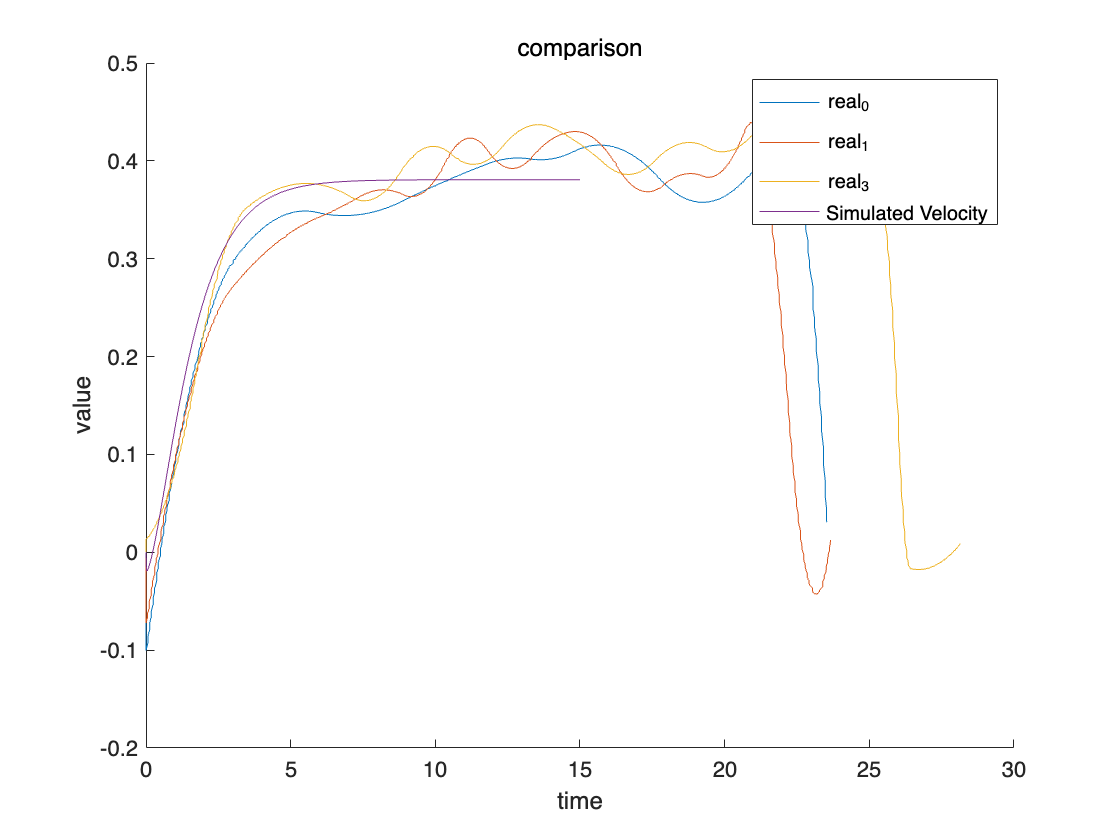

function plot_from_csv(filename, isvel)

filepath = fullfile('/Users/gaoshenghan/Desktop/Matlab_Simu4Unicycle/Export/Matlab/Data', filename);

try
    data = readcell(filepath);
catch
    error("File not found:\n%s", filepath);
end

type = string(data(2:end,1));
vals = data(2:end,2:end);

%% ======================
% TRY
%% ======================
is_try = type == "try";
try_vals = vals(is_try,:);
try_mat = cell2mat(try_vals);

t_try = try_mat(:,1);
x_c = try_mat(:,2);
x_c_dot = try_mat(:,3);

%% ======================
% REAL
%% ======================
is_real = startsWith(type,"real");

real_type = type(is_real);
real_vals = vals(is_real,:);

unique_real = unique(real_type);

figure
hold on

% plot real with NaN split
for i = 1:length(unique_real)

    idx = real_type == unique_real(i);
    r = str2double(string(real_vals(idx,:)));

    %r = r(~any(isnan(r),2),:);

    t = r(:,1);
    v = r(:,2);

    t = [t; NaN];
    v = [v; NaN];

    plot(t, v, 'DisplayName', unique_real(i))
end

% plot try

if isvel
    plot(t_try, x_c_dot, 'DisplayName','Simulated Velocity')
else
    plot(t_try, x_c, 'DisplayName','Simulated Position')
end

legend
xlabel('time')
ylabel('value')
title('comparison')

end

plot_from_csv("Position_tuning_results.csv", false)
plot_from_csv("Velocity_tuning_results.csv", true)